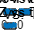

clc;
clear;
path = "C:\Users\AVISH\OneDrive\Desktop\Data_Lab3\Individual\imu.csv";
data = readtable(path,VariableNamingRule="preserve");
header_sec = data.("header.stamp.secs");
header_nsec = data.("header.stamp.nsecs")/(10^9); %convert nano seconds to secs
time = header_sec+header_nsec;
t = time-min(time);

%% GYRO
gx = data.("imu.angular_velocity.x");
gy = data.("imu.angular_velocity.y");
gz = data.("imu.angular_velocity.z");

% Plot gyro x,y,z vs time
figure();
sgtitle("Gyro x, y, z vs. Time (Fig 0)");
subplot(2,2,1);
plotvstime(gx,t,'angluar rate (rad/sec)','Gyro-X vs time')
subplot(2,2,2);
plotvstime(gy,t,'angluar rate (rad/sec)','Gyro-Y vs time')
subplot(2,2,3);
plotvstime(gz,t,'angluar rate (rad/sec)','Gyro-Z vs time')

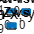



%% ACCELERATION
ax = data.("imu.linear_acceleration.x");
ay = data.("imu.linear_acceleration.y");
az = data.("imu.linear_acceleration.z");

% Plot accel x,y,z vs time
figure();
sgtitle("Linear Acceleration x, y, z vs. Time (Fig 1)");
subplot(2,2,1);
plotvstime(ax,t,'acceleration (m/sec^2)','Accel-X vs time')
subplot(2,2,2);
plotvstime(ay,t,'acceleration (m/sec^2)','Accel-Y vs time')
subplot(2,2,3);
plotvstime(az,t,'acceleration (m/sec^2)','Accel-Z vs time')

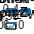



%% ORIENTATION
qx = data.("imu.orientation.x");
qy = data.("imu.orientation.y");
qz = data.("imu.orientation.z");
qw = data.("imu.orientation.w");

%convert back from quaternion to euler
q= [qw,qx,qy,qz];
euler=rad2deg(quat2eul(q));
yaw = euler(:,1);
pitch = euler(:,2);
roll = euler(:,3);

% Plot oreintation x,y,z vs time
figure();
sgtitle("Orientation x, y, z vs. Time (Fig 2)");
subplot(2,2,1);
plotvstime(roll,t,'roll (degrees)','Oreintation-X vs time')
subplot(2,2,2);
plotvstime(pitch,t,'pitch (degrees)','Oreintation-Y vs time')
subplot(2,2,3);
plotvstime(yaw,t,'yaw (degrees)','Oreintation-Z vs time')

## NOISE ANALYSIS

%% ACCELERATION
% X
[MEAN_AX,MEADIAN_AX,STD_AX]=noisestat(ax)

MEAN_AX = 0.0635

MEADIAN_AX = 0.0640

STD_AX = 0.0125

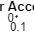

title('Histogram-Linear Acceleration X(Fig 3)')
xlabel('acceleration (m/sec^2)')
ylabel('Number of Readings')

% Y
[MEAN_AY,MEADIAN_AY,STD_AY]=noisestat(ay)

MEAN_AY = -0.0120

MEADIAN_AY = -0.0120

STD_AY = 0.0122

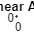

title('Histogram-Linear Acceleration Y')
xlabel('acceleration (m/sec^2)')
ylabel('Number of Readings')

% Z
[MEAN_AZ,MEADIAN_AZ,STD_AZ]=noisestat(az)

MEAN_AZ = -9.8479

MEADIAN_AZ = -9.8480

STD_AZ = 0.0181

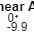

title('Histogram-Linear Acceleration Z')
xlabel('acceleration (m/sec^2)')
ylabel('Number of Readings')



%% GYRO

% X
[MEAN_GX,MEADIAN_GX,STD_GX]=noisestat(gx)

MEAN_GX = 5.4916e-05

MEADIAN_GX = 5.1000e-05

STD_GX = 6.4332e-04

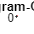

title('Histogram-Gyro X')
xlabel('angluar rate (rad/sec)')
ylabel('Number of Readings')

% Y
[MEAN_GY,MEADIAN_GY,STD_GY]=noisestat(gy)

MEAN_GY = 1.0977e-04

MEADIAN_GY = 1.4300e-04

STD_GY = 0.0019

title('Histogram-Gyro Y')
xlabel('angluar rate (rad/sec)')
ylabel('Number of Readings')

% Z
[MEAN_GZ,MEADIAN_GZ,STD_GZ]=noisestat(gz)

MEAN_GZ = 2.1887e-04

MEADIAN_GZ = 2.2000e-04

STD_GZ = 6.9618e-04

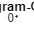

title('Histogram-Gyro Z')
xlabel('angluar rate (rad/sec)')
ylabel('Number of Readings')

function plotvstime(omega,time,Ylabel,Title)
% function to plot signal vs time
plot(time,omega)
xlabel('time (sec)')
ylabel(Ylabel)
title(Title)
xlim([0 max(time)])
end

function [avg,med,st]=noisestat(omega)
avg = mean(omega);
med = median(omega);
st=std(omega);
figure();
histfit(omega)
end


